https://alessandromastrofini.it/deep-learning-segmentazione/

clear all; close all; 

% set current file path 
filePath = matlab.desktop.editor.getActiveFilename;
pathDivided=strsplit(filePath,'\');
newPath=erase(filePath,pathDivided(end));
dataPath=strcat(newPath,'dataset');
net=resnet50;
numClasses=3; % foreground and background
imageSize=net.Layers(1).InputSize; %read size directly from net
imdsTEST = imageDatastore(strcat(newPath,'dataset\mole\TEST\Immagini')); % link for training frame

addpath(strcat(newPath,'functions')); %set path for functions

erosion element:


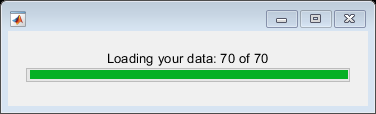

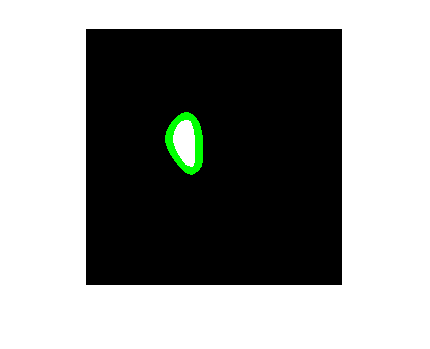

pathImage = strcat(newPath,'dataset\mole\Immagini'); % link for training frame
pathGT=strcat(newPath,'dataset\mole\Segmentazioni');
pathExport=strcat(newPath,'dataset\mole\PROCESSED\');
%[imds,pxds]=optimizeDataset(pathImage,pathGT,pathExport,elementSize,imageSize)
[imds,pxds]=optimizeDataset(pathImage,pathGT,pathExport,8,imageSize);

% not use this path 
%pxds = pixelLabelDatastore(strcat(pathExport,'GT'),["BACK","BORDER","INSIDE"],[0 1 2]); % link for GT images
%imds = imageDatastore(strcat(pathExport,'IMG'));

# Pre Training

[options,lgraph,dsTrain]=preTrainMyNet(imds, pxds,imageSize,numClasses);

# Training 

[net, info]= trainNetwork(dsTrain,lgraph,options);

Net ready fro Training


Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |       29.19% |       1.2461 |          0.0100 |
|       3 |          50 |       00:00:42 |       83.88% |       0.5552 |          0.0100 |
|       6 |         100 |       00:01:21 |       89.70% |       0.2652 |          0.0100 |
|       9 |         150 |       00:02:03 |       86.49% |       0.2954 |          0.0100 |
|      12 |         200 |       00:02:45 |       87.87% |       0.3594 |          0.0100 |
|      15 |         250 |       00:03:27 |       84.72% |       0.3371 |          0.0100 |
|      18 |         300 |  

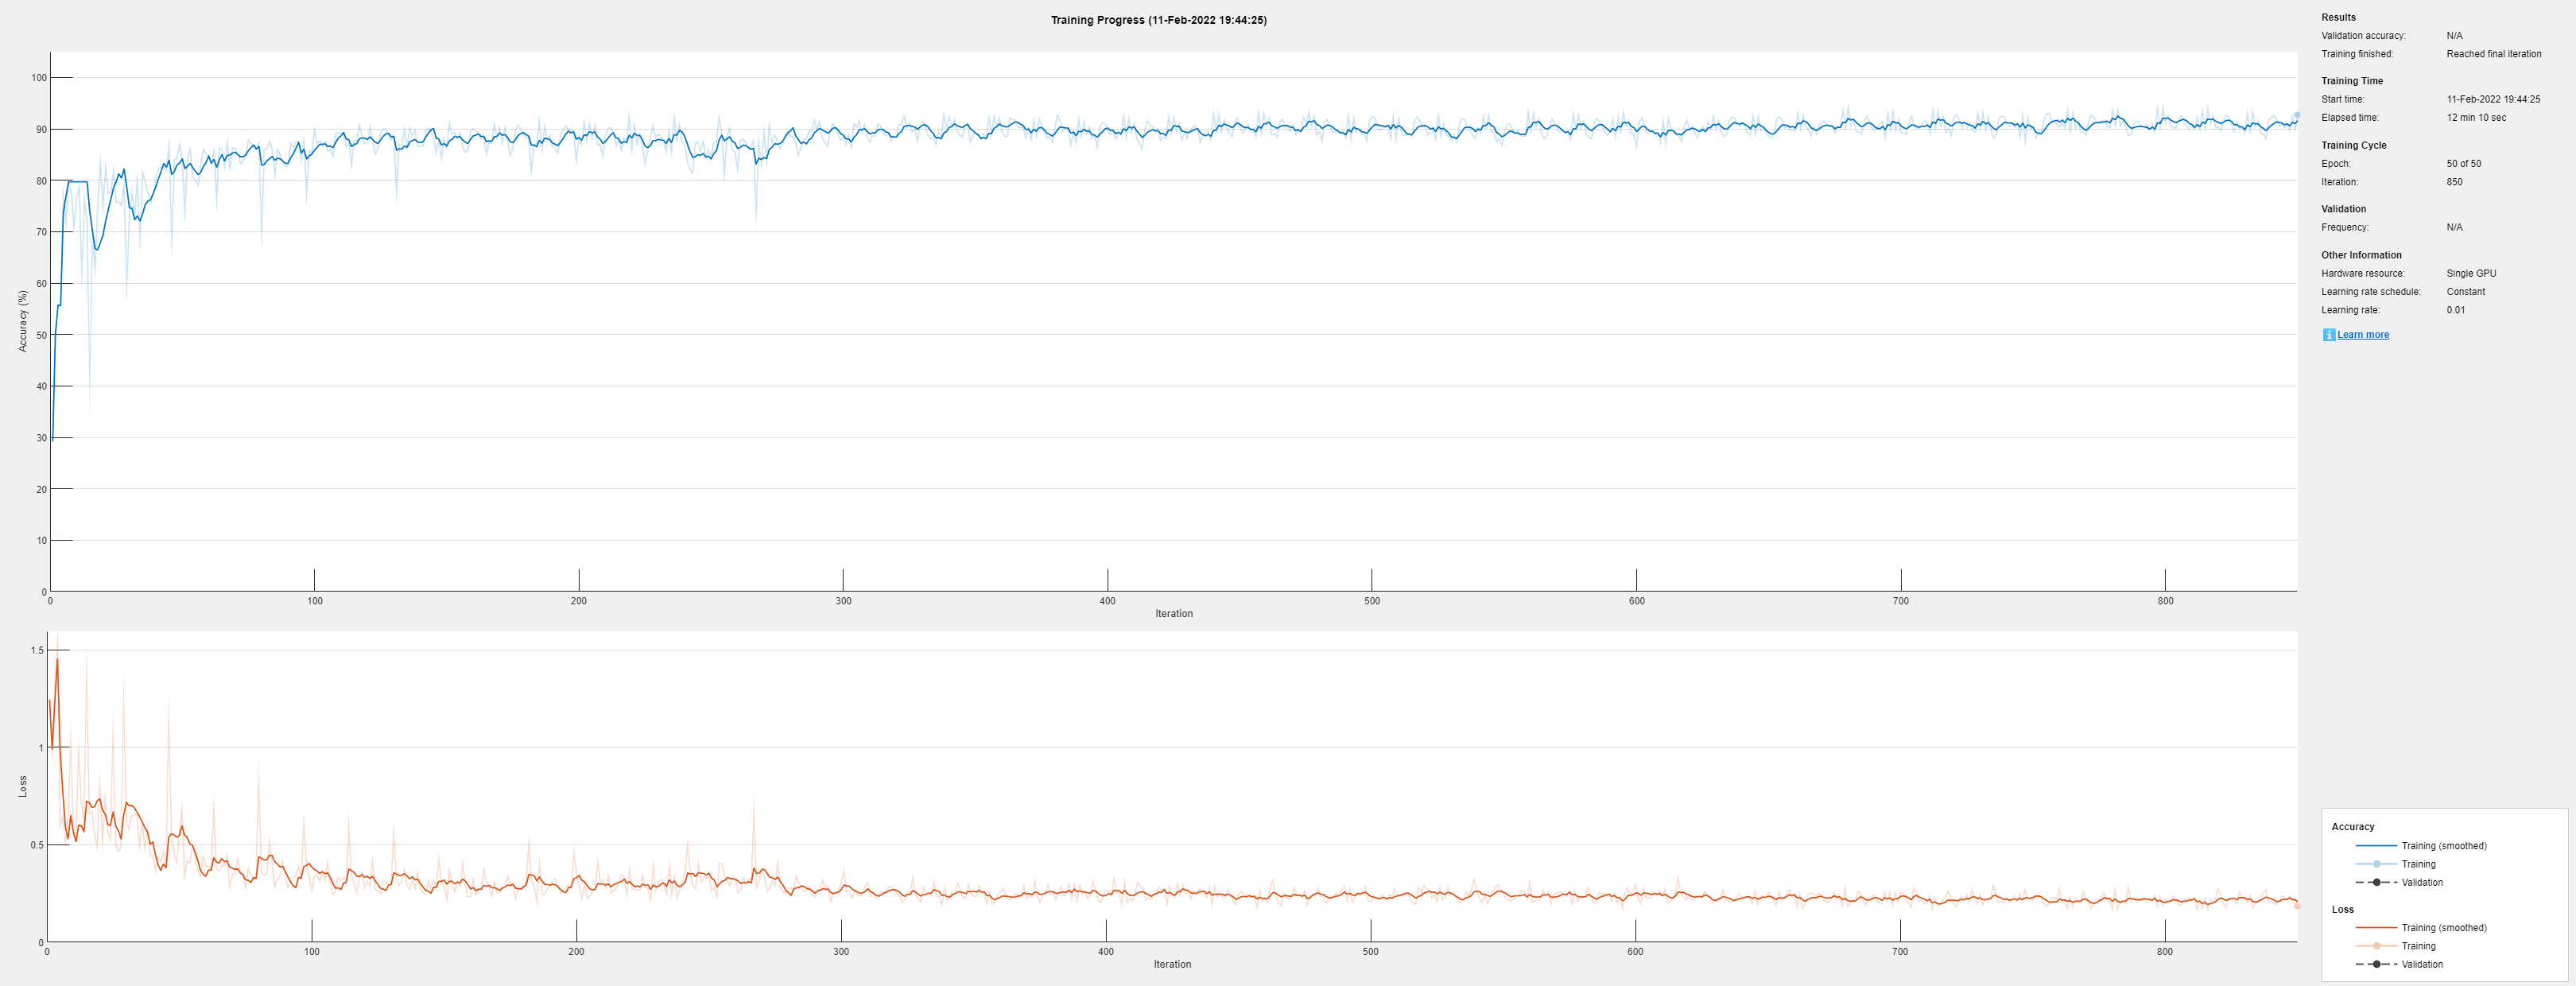

plot(1:length(info.TrainingAccuracy),info.TrainingAccuracy,'Color','#0072BD')

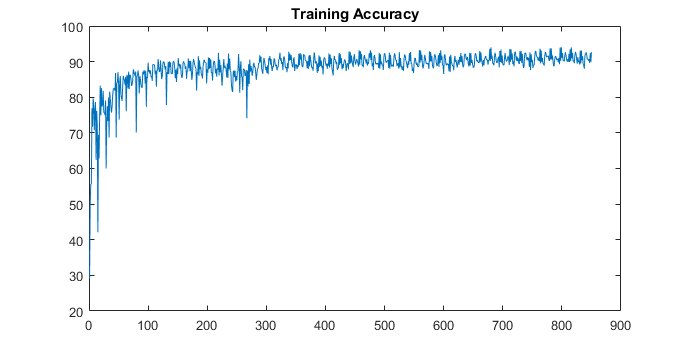

title('Training Accuracy')
subfigure(2,1,2);
plot(info.TrainingLoss,'Color','#D95319')

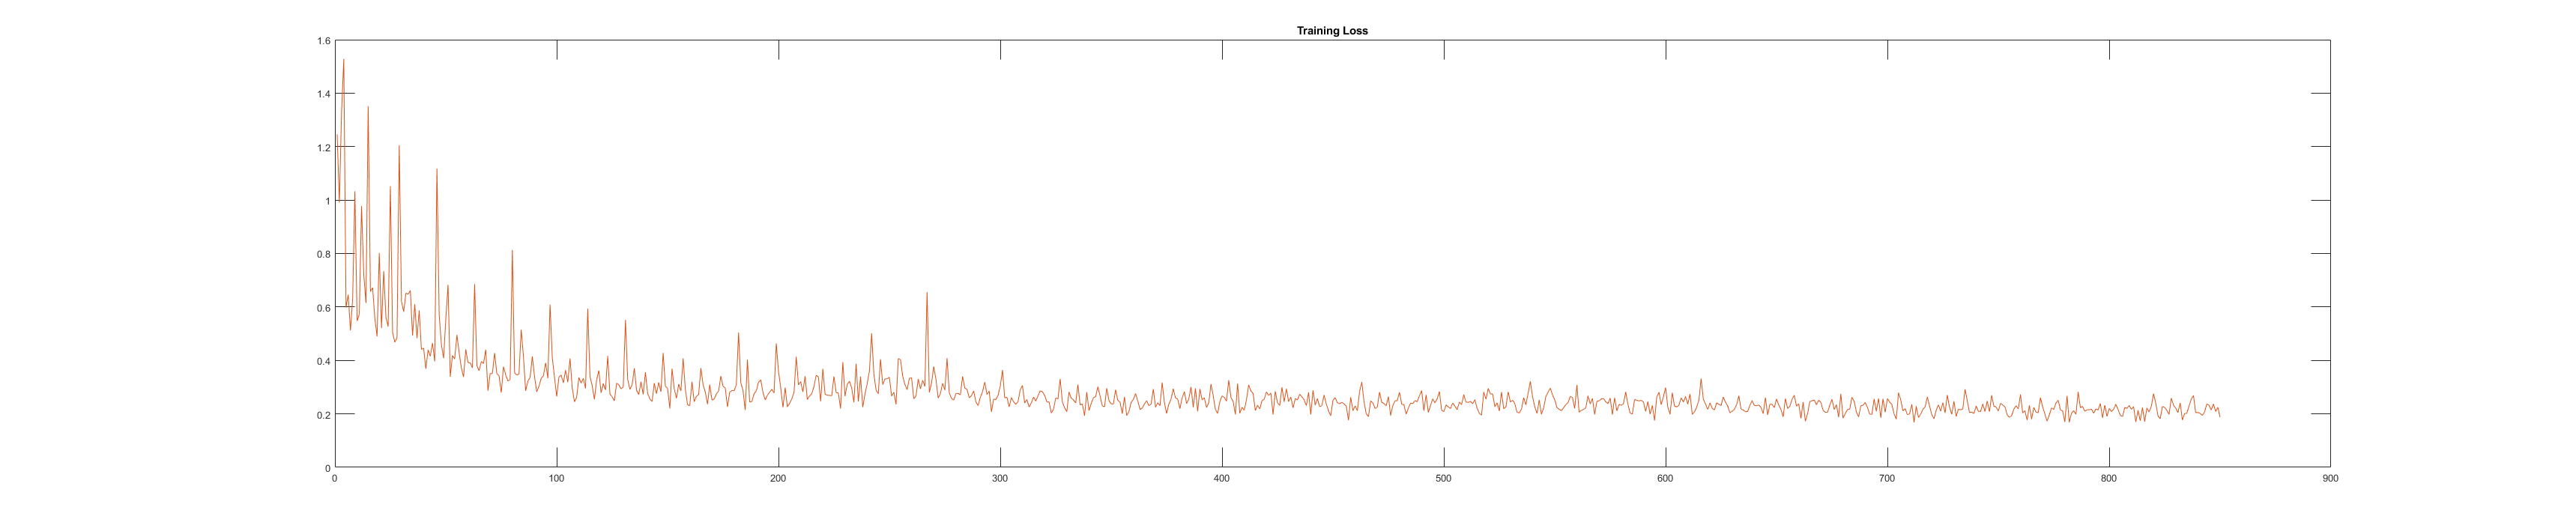

title('Training Loss')
accuracy=info.TrainingAccuracy(end);
loss=info.TrainingLoss(end);

# Testing

%[area]=testBorderSegmentation(imdsTEST,index,net,'mode');
%[area]=testBorderSegmentation(imdsTEST,2,net,'verbose'); 
% set mode to 'verbose' to see all the classifications images
% otherwise only pair images
% index in range [1;30]

[area]=testBorderSegmentation(imdsTEST,28,net,'NO');

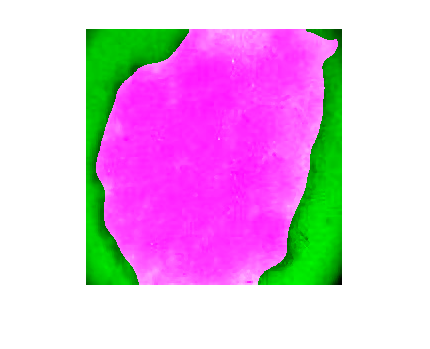

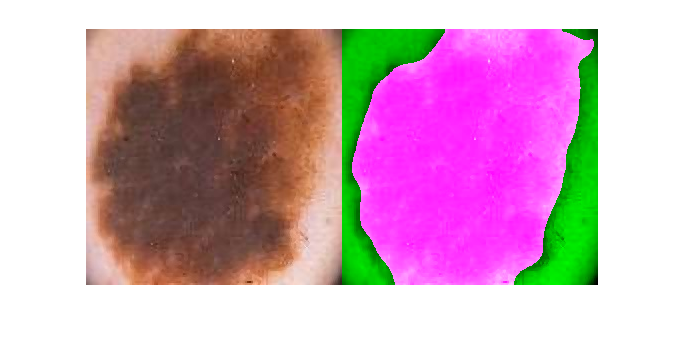

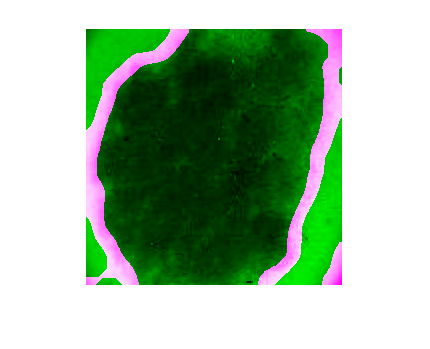

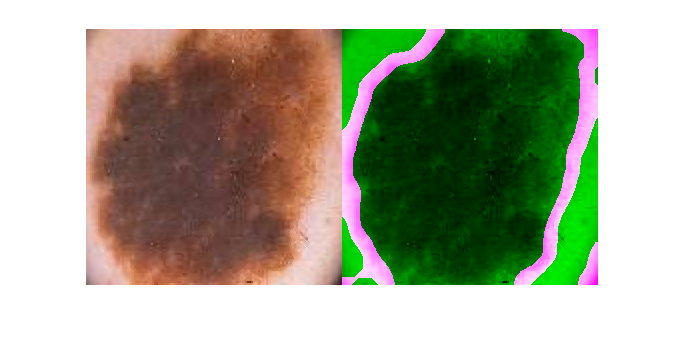

internal area: 72.3953 %


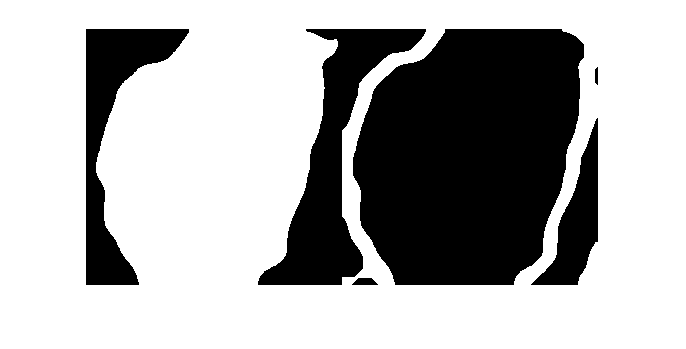

inside:


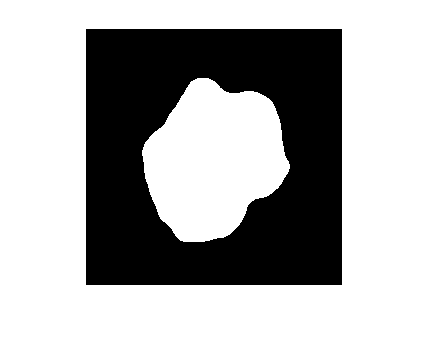

border:


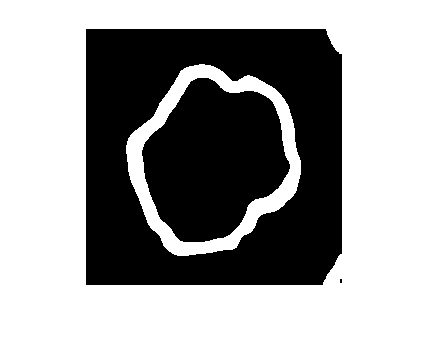

back:


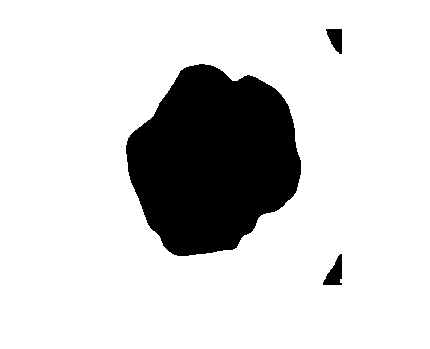

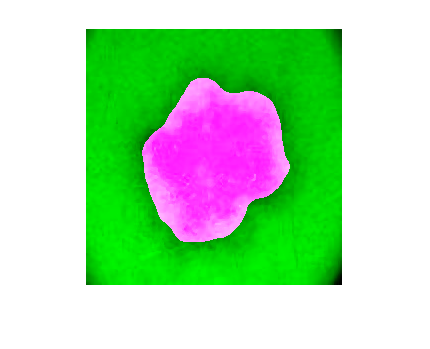

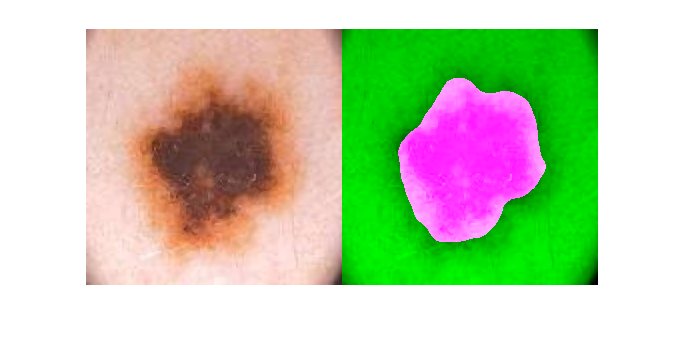

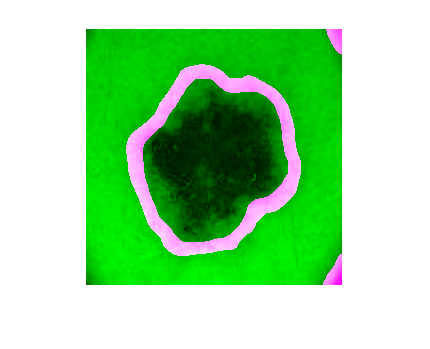

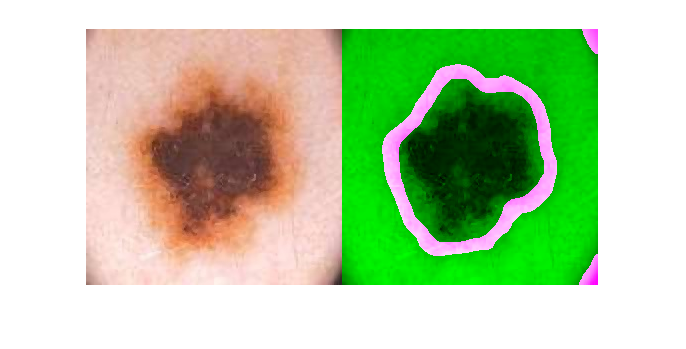

internal area: 25.769 %


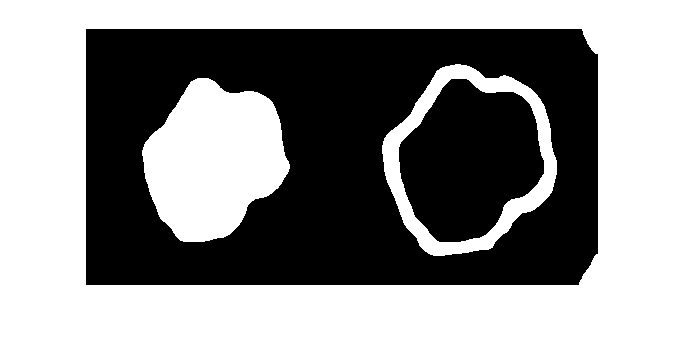

[area]=testBorderSegmentation(imdsTEST,30,net,'verbose');